# HW03 - Scuderi -1937090

## Problem 1

Use a simple plant, define its augmented plant and study its singular value decomposition treating it as a MIMO system.

clear all
s = tf('s');

% SISO original Plant
G = 1/(s+10)

G =
 
    1
  ------
  s + 10
 
Continuous-time transfer function.
Model Properties


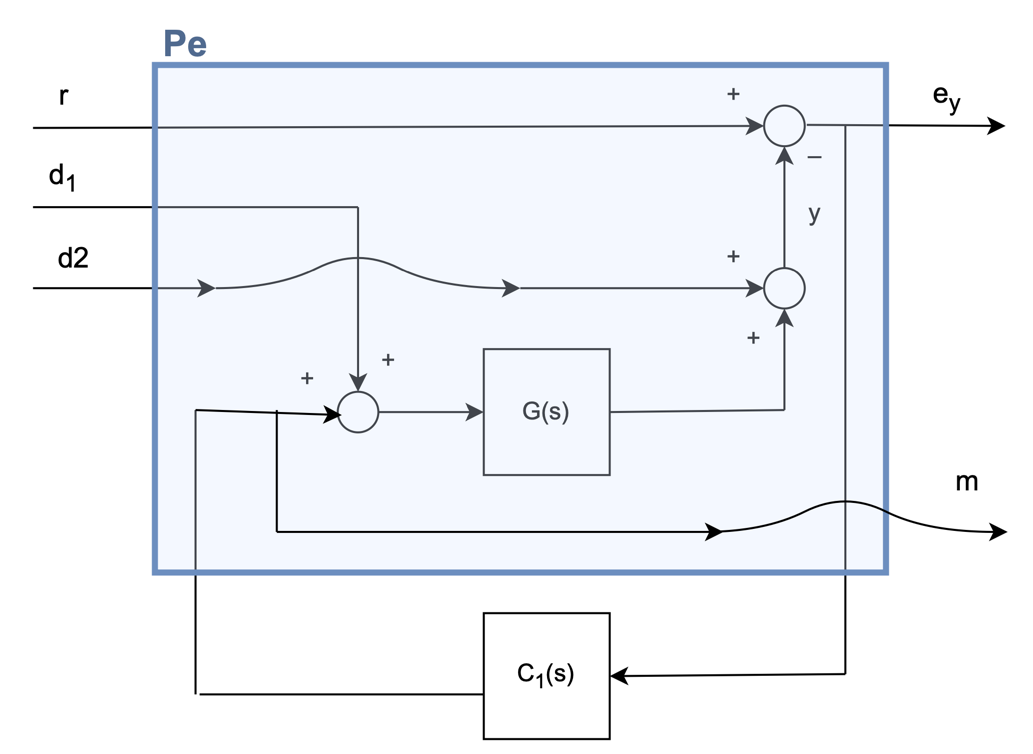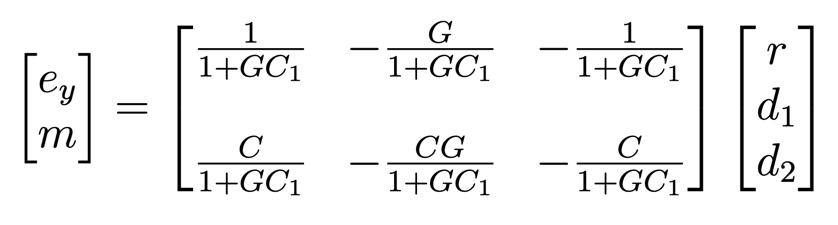

### Spec1: W1(0) Gain

% Closed Loop Augmented Plant
C1 = 10/s;
L1 = G*C1;
W1 = [1/(1+L1) -G/(1+L1) -1/(1+L1);
    C1/(1+L1) -L1/(1+L1) -C1/(1+L1)];

% W1(0) gain
W1_0 = freqresp(W1, 0)

W1_0 =      0     0     0
    10    -1   -10


% Singular Value Decomposition
[U, S, V] = svd(W1_0)

U =      0    -1
     1     0


S =    14.1774         0         0
         0         0         0


V =     0.7053   -0.7089         0
   -0.0705   -0.0702   -0.9950
   -0.7053   -0.7018    0.0995


#### Null Space of W1(0)

% Null(W1(0)) = span{v21,v22}
v21 = V(:,2);
v22 = V(:,3);
[v21, v22]

ans =    -0.7089         0
   -0.0702   -0.9950
   -0.7018    0.0995


#### Null Space of W1(0)^T

% % Null(W1(0)^T) = span{u2}
u2 = U(:,2)

u2 =     -1
     0


## System Response

To easily simulate disturbances without using many Matlab commands, I used Simulink to simulate and exported the simulation data in .mat files. The plotting is made here to add more "readability" to them. The simulation however can be run at any time in the simulink file.

#### Response for input direction belonging to Null(W1(0))

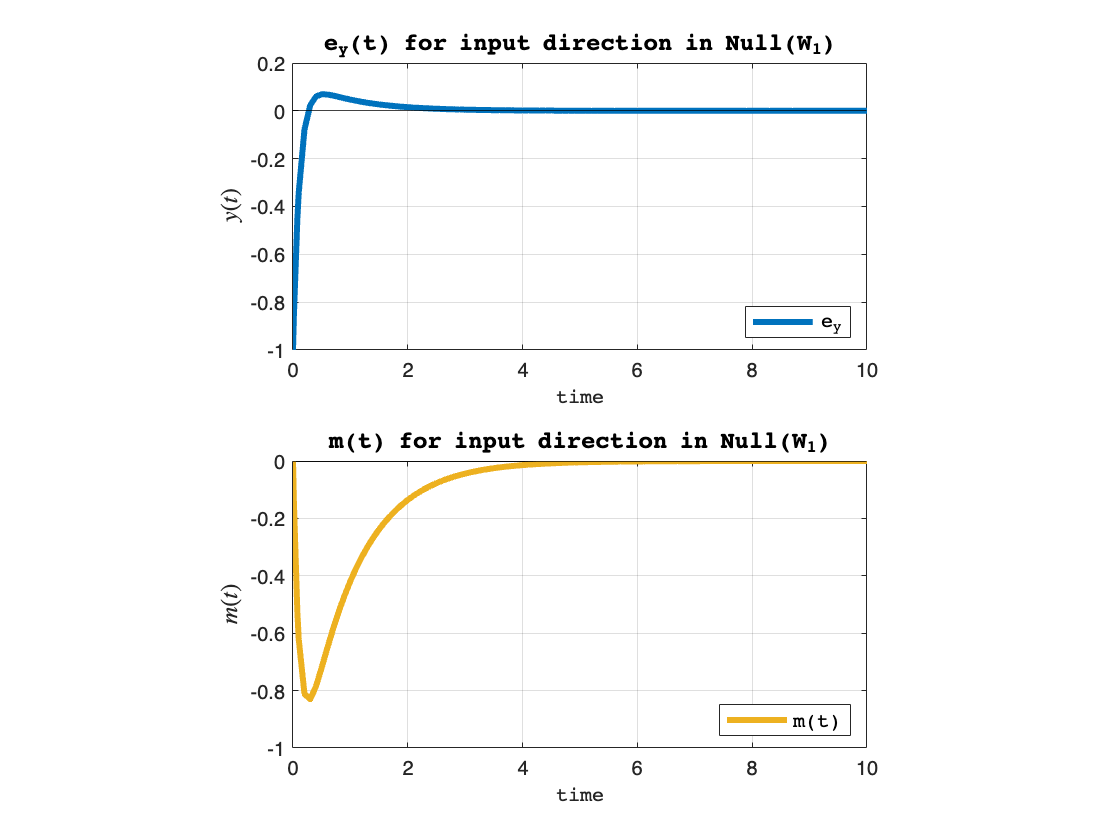

% Load data for input along v2
ey_v2 = load('Data/ey_v2.mat');
m_v2 = load('Data/m_v2.mat');

% Extract simulation time vector
t = ey_v2.ans.Time;

% Extract tracking error and control effort vectors
ey_v2 = ey_v2.ans.Data;
m_v2 = m_v2.ans.Data;


figure
subplot(2,1,1)
plot(t,ey_v2(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('e_y(t) for input direction in Null(W_1)','FontName','courier','FontSize',12)
legend('e_y','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

subplot(2,1,2)
plot(t,m_v2(:),'LineWidth',3, 'Color','#EDB120'); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('m(t) for input direction in Null(W_1)','FontName','courier','FontSize',12)
legend('m(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

#### Response for input direction belonging to Range(W1(0))

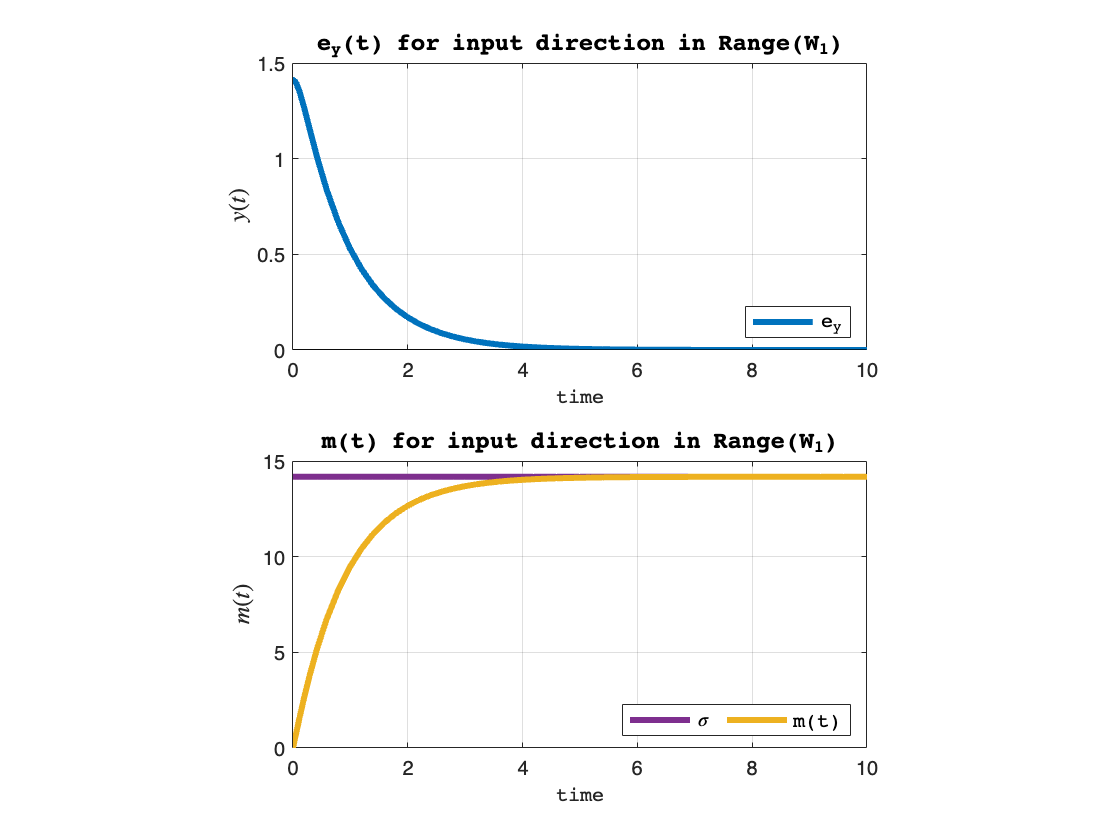

% Load data for input along v1
ey_v1 = load('Data/ey_v1.mat');
m_v1 = load('Data/m_v1.mat');

% Extract simulation time vector
t = ey_v1.ans.Time;

% Extract tracking error and control effort vectors
ey_v1 = ey_v1.ans.Data;
m_v1 = m_v1.ans.Data;


figure
subplot(2,1,1)
plot(t,ey_v1(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('e_y(t) for input direction in Range(W_1)','FontName','courier','FontSize',12)
legend('e_y','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

subplot(2,1,2)
plot(t,S(1,1)*ones(size(t)),'LineWidth',3, 'Color','#7E2F8E');
hold on 
plot(t,m_v1(:),'LineWidth',3, 'Color','#EDB120'); grid
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('m(t) for input direction in Range(W_1)','FontName','courier','FontSize',12)
legend('\sigma','m(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

#### Response for general input direction (1 1 1)T

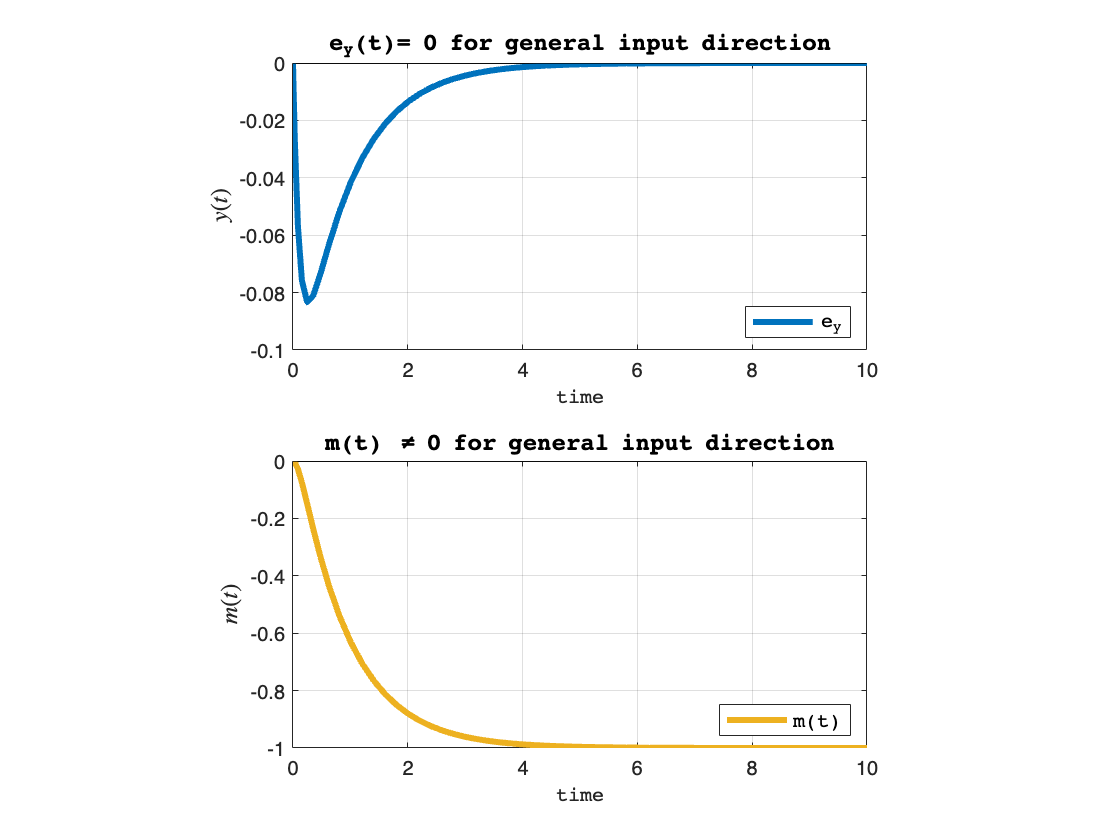

% Load data for a general input direction
ey_any = load('Data/ey_any.mat');
m_any = load('Data/m_any.mat');

% Extract simulation time vector
t = ey_any.ans.Time;

% Extract tracking error and control effort vectors
ey_any = ey_any.ans.Data;
m_any = m_any.ans.Data;


figure
subplot(2,1,1)
plot(t,ey_any(:),'LineWidth',3); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('e_y(t)= 0 for general input direction','FontName','courier','FontSize',12)
legend('e_y','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

subplot(2,1,2)
plot(t,m_any(:),'LineWidth',3, 'Color','#EDB120'); grid
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('m(t) \neq 0 for general input direction','FontName','courier','FontSize',12)
legend('m(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

## Spec2: W2($\omega$) Gain, $\omega =10$

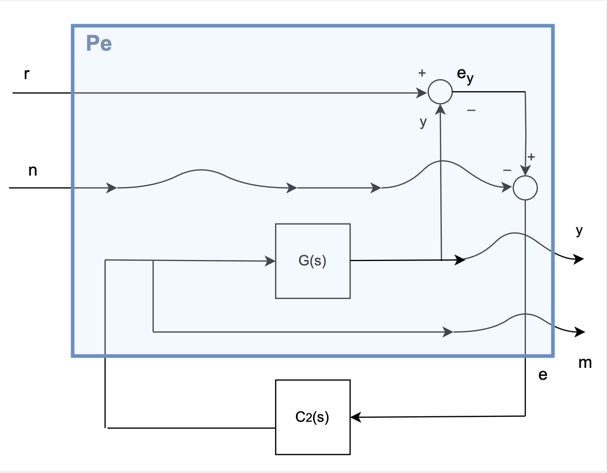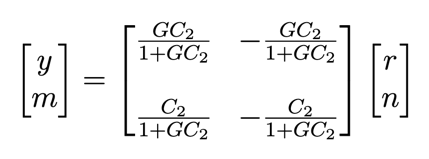

% "Nominal" SISO H-inf controller design 
%% Sensitivity Weight
Ms = 3;
B3s = 20;
As = 0.1;

%% Complementary Sensitivity Weight
Mt = 1.001;
B3t = 100;
At = 0.1;

wS = (s/Ms+B3s)/(s+B3s*As);

wT = (s+(B3t/Mt))/(At*s+B3t);

[C2,~,GAM1] = mixsyn(G,wS, [],wT);
GAM1

GAM1 = 1.0039

Let's verify if the controller tracks the reference  correctly in absence of measurement noise

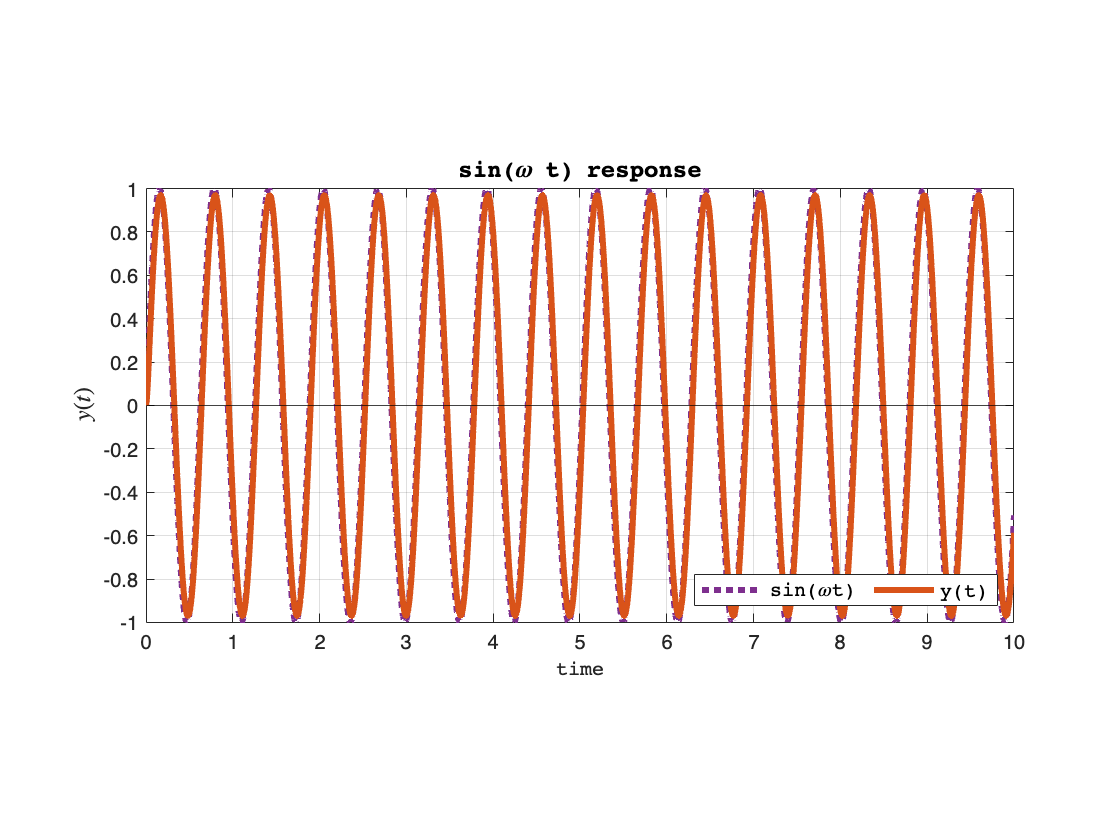

% Closed Loop Sensitivities
CLoop = loopsens(G,C2);
t = 0:0.01:10;

% Reference to be tracked
u2 = sin(10.*t);

% Closed Loop Response wirh no measurement noise
[y2, ~] = lsim(CLoop.To, u2, t);

% Closed Loop control effort wirh no measurement noise
%[m2, ~] = lsim(CLoop.CSo, u2, t);

figure
plot(t, u2(:), ':','Color', '#7E2F8E','LineWidth', 3)
hold on
plot(t,y2(:), 'LineWidth', 3,'Color','#D95319'); 
grid;
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
hold off
pbaspect([2 1 1])
title('sin(\omega t) response','FontName','courier','FontSize',12)
legend('sin(\omegat)','y(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)

### W2($\omega$) Gain

t = 0:0.01:10;
L2 = G*C2;

% Augmented Closed Loop W2(s)
W2 = minreal([L2/(1+L2) -L2/(1+L2);
    C2/(1+L2) -C2/(1+L2)]);

31 states removed.


% W2(10) "gain"
W2_10 = freqresp(W2, 10);

% Singular Value Decomposition
[U, S, V] = svd(W2_10)

U =   -0.0700 + 0.0084i   0.7056 - 0.7050i
  -0.7842 - 0.6164i  -0.0705 - 0.0000i


S =    19.4589         0
         0    0.0000


V =   -0.7071 + 0.0000i   0.7071 + 0.0000i
   0.7071 + 0.0000i   0.7071 + 0.0000i


% Analize "complex directions"
[phasev1,magv1] = cart2pol(real(V(:,1)),imag(V(:,1)));
[phasev2,magv2] = cart2pol(real(V(:,2)),imag(V(:,2)));
[phaseu1,magu1] = cart2pol(real(U(:,1)),imag(U(:,1)));
[phaseu2,magu2] = cart2pol(real(U(:,2)),imag(U(:,2)));

#### Maximum input direction


$${\bf u}_{max}(t) = \left[\matrix{|v_{11}|\sin(\bar\omega  t + \angle v_{11}) \cr |v_{12}|\sin(\bar\omega  t + \angle v_{12}) } \right]$$


% Input for obtaining maximum amplification
input_max = magv1.*sin(10*t + phasev1);

% Maximum aplified output
output_max = S(1,1)*magu1.*sin(10*t+phaseu1);

% Input for obtaining Null Output
input_min = magv2.*sin(10*t+phasev2);

% (Zero output)
output_min = round(S(2,2))*magu2.*sin(10*t+phaseu2);

Let's see the simulation results on simulink

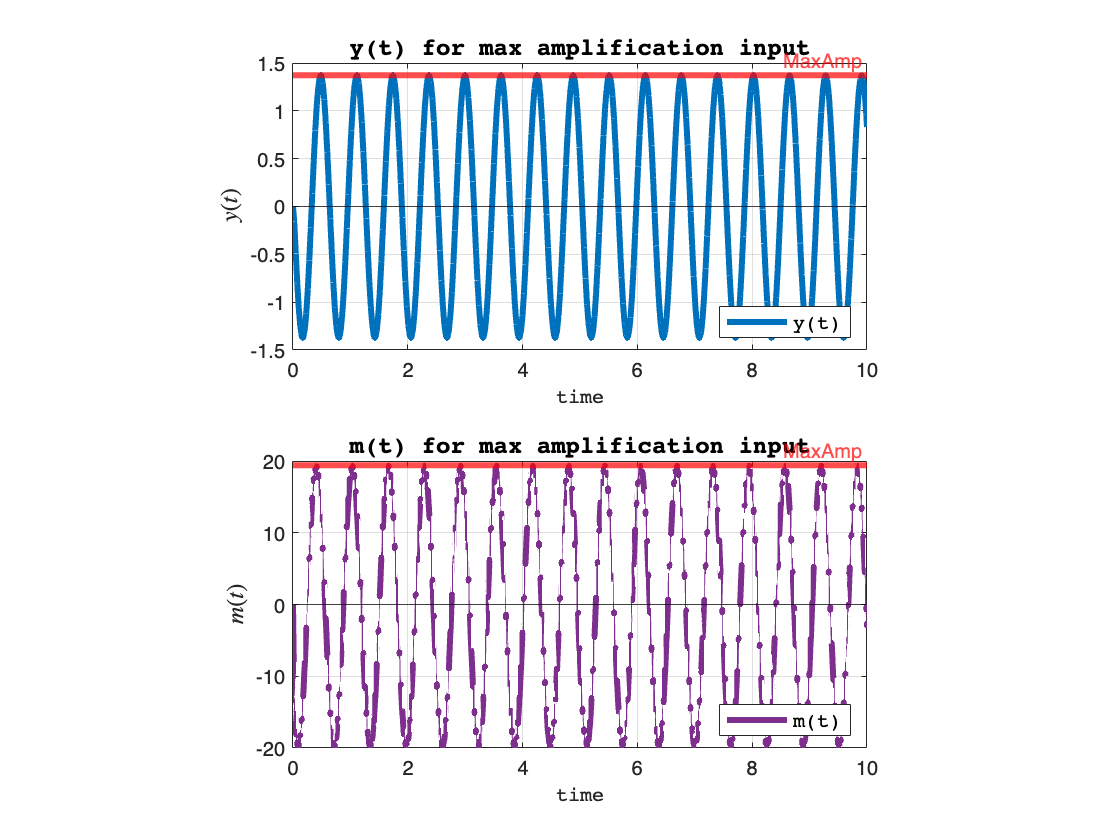

% Load data for a general input direction
y2_max = load('Data/y2_max.mat');
m2_max = load('Data/m2_max.mat');

% Extract simulation time vector
t = y2_max.ans.Time;

% Extract tracking error and control effort vectors
y2_max = y2_max.ans.Data;
m2_max = m2_max.ans.Data;


figure
subplot(2,1,1)
plot(t,y2_max(:),'LineWidth',3); grid
yline(S(1,1)*magu1(1),'r', 'LineWidth', 3,'Label','MaxAmp');
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$y(t)$','Interpreter','latex','FontSize',12)
title('y(t) for max amplification input','FontName','courier','FontSize',12)
legend('y(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

subplot(2,1,2)
plot(t,m2_max(:),'LineWidth',3, 'Color','#7E2F8E'); grid
yline(S(1,1)*magu1(2),'r', 'LineWidth', 3,'Label','MaxAmp');
yline(0,'-k');
xlabel('time','FontName','courier','FontSize',10)
ylabel('$m(t)$','Interpreter','latex','FontSize',12)
title('m(t) for max amplification input','FontName','courier','FontSize',12)
legend('m(t)','FontName','courier','FontSize',10,...
    'Location','southeast','NumColumns',3)
pbaspect([2 1 1])

# Problem 2: MSD system

%MSD Parameters
% system parameters
m  = 50; % mass
mu = 2; % "low" viscous friction coefficient
k  = 20; % spring coefficient


% Motor Parameters from:
% https://www.researchgate.net/publication/272102820_Parameters_Identification_of_a_Permanent_Magnet_DC_Motor/figures?lo=1

% Motor Parameters
Kt = 1.835;
Ke = 1.835;
L = 0.104;
R = 3.05;

% Wheel Radius
r = 0.35;

A = [0 1 0;
    -k/m -mu/m Kt/(m*r);
    0 -Ke/L -R/L];

B = [0 0; 0 1/m; 1/(L*r) 0];
C = [1 0 0; 0 0 1];
D = [0 0; 0 0];

s = tf('s');
G_ss = ss(A,B,C,D);
G_ss.u = ['V(t)';'f(t)'];
G_ss.y = ['x(t)';'i(t)'];

[N1,D1] = ss2tf(A,B,C,D,1);
[N2,D2] = ss2tf(A,B,C,D,2);

%G11 = (Kt/r^2)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G11 = tf(N1(1,:),D1);

%G12 = (R + L*s)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G12 = tf(N2(1,:),D2);

%G21 = ((m*s^2 + mu*s + k)/r)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G21 = tf(N1(2,:),D1);

%G22 = (-Ke*s)/( (L*m)*s^3 + (L*mu + R*m)*s^2 + (Ke*Kt/r + R*mu + L*k)*s + (R*k) )
G22 = tf(N2(2,:),D2);
G = minreal([G11 G12; G21 G22]);
G.u = ['V(t)';'f(t)'];
G.y = ['x(t)';'i(t)']

G =
 
  From input "V(t)" to output...
                        2.881
   x(t):  ---------------------------------
          s^3 + 29.37 s^2 + 3.423 s + 11.73
 
             27.47 s^2 + 1.099 s + 10.99
   i(t):  ---------------------------------
          s^3 + 29.37 s^2 + 3.423 s + 11.73
 
  From input "f(t)" to output...
                   0.02 s + 0.5865
   x(t):  ---------------------------------
          s^3 + 29.37 s^2 + 3.423 s + 11.73
 
                -0.3529 s - 6.926e-17
   i(t):  ---------------------------------
          s^3 + 29.37 s^2 + 3.423 s + 11.73
 
Continuous-time transfer function.


pole(G)

ans =  -29.2636 + 0.0000i
  -0.0516 + 0.6310i
  -0.0516 - 0.6310i
 -29.2636 + 0.0000i
  -0.0516 + 0.6310i
  -0.0516 - 0.6310i


% Condition number
G0 = freqresp(G,0);
[U,S,V] = svd(G0)

U =    -0.2542   -0.9671
   -0.9671    0.2542


S =     0.9685         0
         0    0.0484


V =    -0.9999    0.0131
   -0.0131   -0.9999


disp(strcat("Condition Number: ", num2str(S(1,1)/S(2,2))))

Condition Number: 20.0263


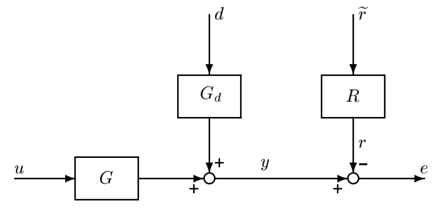

%scale the input
w_u1 = 2; % Max armature voltage 
w_u2 = 10; % Max winch traction force 
Du = [w_u1 0; 0 w_u2];

%scale the reference
w_r1 = 1; % maximum desired position
w_r2 = 1; % maximum desired current
Dr = [w_r1 0; 0 w_r2];

%scale tracking error
w_e1 = 0.01; % maximum allowed position error
w_e2 = 0.1; % maximum allowed current error
De = [w_e1 0; 0 w_e2];

R = inv(De)*Dr; 

G2 = inv(De)*G*Du;

% Condition number
G0 = freqresp(inv(De)*G*Du,0);
[U,S,V] = svd(G0);


# Problem 3

## Ex. 1

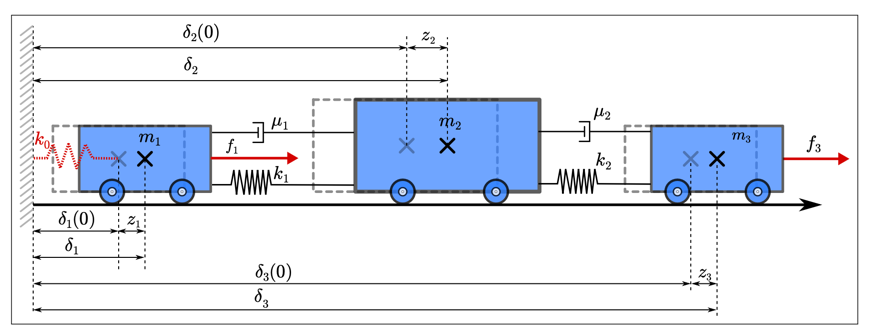

m1 =1; 
m2 =1.5;
m3 =0.5;
k0 =5;
k1 =10;
k2 =100;
mu1 = 5;
mu2 = 15;
d1 = 0.1; 
d2 = 0.2; 
d3 = 0.1;
A11 = zeros(3,3);
A12 = eye(3);
A21 = [-(k0+k1)/m1 k1/m1 0;
        k1/m2 -(k1+k2)/m2 k2/m2;
        0 k2/m3 -k2/m3];
A22 = [-(mu1+d1)/m1 mu1/m1 0;
        mu1/m2 -(mu1+mu2+d2)/m2 mu2/m2
        0 mu2/m3 -(mu2+d3)/m3];
A = [A11, A12;
    A21, A22];
B = [zeros(3,2); 1/m1 0; 0 0; 0 1/m3];

C = [[1 0 0; 0 0 1], zeros(2,3)];

D = zeros(2,2);


MSD = minreal(ss(A,B,C,D));

MSD.StateName = {'m1 displacement (m)';'m2 displacement (m)';'m3 displacement (m)';...
                  'm1 velocity (m/s)';'m2 velocity (m/s)';'m3 velocity (m/s)'};
MSD.y  = {'z1','z3'};
MSD.u = {'f1';'f3';};

G = tf(minreal(MSD));


## Augmented Plant

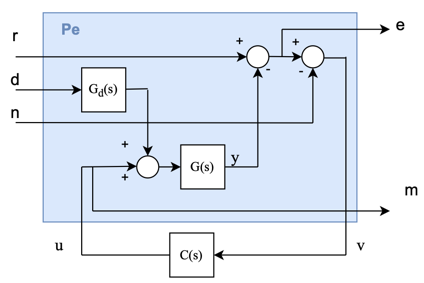

G.u = 'u_bar'; G.y = 'y';

Gd = tf([0.1; 0]); Gd.u = 'd'; Gd.y = 'd_bar';

Sum1 = sumblk('ey = r - y',2);
Sum2 = sumblk('v = ey - n',2);
Sum3 = sumblk('u_bar = u + d_bar',2);

Pe = minreal(connect(G, Gd, Sum1,Sum2,Sum3, {'r','d','n','u'},{'ey','u','v'}));

6 states removed.


#### Controllers Design

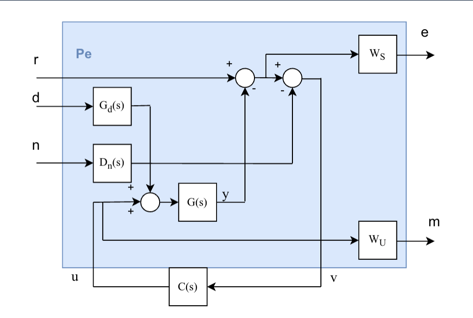

% Mixsyn Sensitivity Weight
Ms1 = 1.001;
B3s1 = 0.7;
As1 = 0.001;

Ws1 = (s/Ms1+B3s1)/(s+B3s1*As1);

wS = eye(2)*Ws1; wS.u = 'ey'; wS.y = 'ey_sens';

% Hinfsyn Sensitivity Weight
Ms2 = 1.01;
B3s2 = 0.8;
As2 = 0.01;

Ws2 = (s/Ms2+B3s2)/(s+B3s2*As2);

wS_hinf = [Ws2 0; 0 Ws2];
wS_hinf.u = 'ey'; wS_hinf.y = 'ey_sens';

% Control Sensitivity Weight
wU = tf([1/100 0; 0 1/100]); wU.u = 'u'; wU.y = 'u_sens';

% Noise Weight Scaling Matrix
Dn = tf(0.1*eye(2)); Dn.u ='n_bar'; Dn.y = 'n';

% Augmented Plant for Controller Synthesis
Pe_syn = minreal(connect(G, Gd, Sum1,Sum2,Sum3, wS_hinf, wU,Dn, {'r','d','n_bar','u'},{'ey_sens','u_sens','v'}));

6 states removed.


% Controller Synthesis with Hinfsyn
[C1,CL,gam] = hinfsyn(Pe_syn,2,2);
gam

gam = 9.9516

% Controller Synthesis with Mixsyn
[C2,CL2,gam2] = mixsyn(G,wS,wU,[]);
gam2

gam2 = 1.0256

#### Closed Loop simulation

% Closed Loop Hinfsyn
CLoop1 = lft(Pe, C1);

% Closed Loop Mixsyn
CLoop2 = lft(Pe, C2);

% Simulation time
t = 0:0.01:10;

% Position reference [r1 r3]
r = [0.5; 1.5];

% Disturbance on first mass (scaled)
d = 1;

% Generate random noise
noise = ones(2,length(t));
for i=1:length(t)
    noise(:,i) = 0.01*rand(2,1);
end

% Input vector for augmented plant
input = [ones(2,length(t)).*r;
        ones(1,length(t))*d;
        noise];

% Augmented plant output with Hinfsyn Controller
[y1, t1] = lsim(CLoop1, input, t);

% Augmented plant output with Mixsyn Controller
[y2, t2] = lsim(CLoop2, input, t);

#### Response Plot

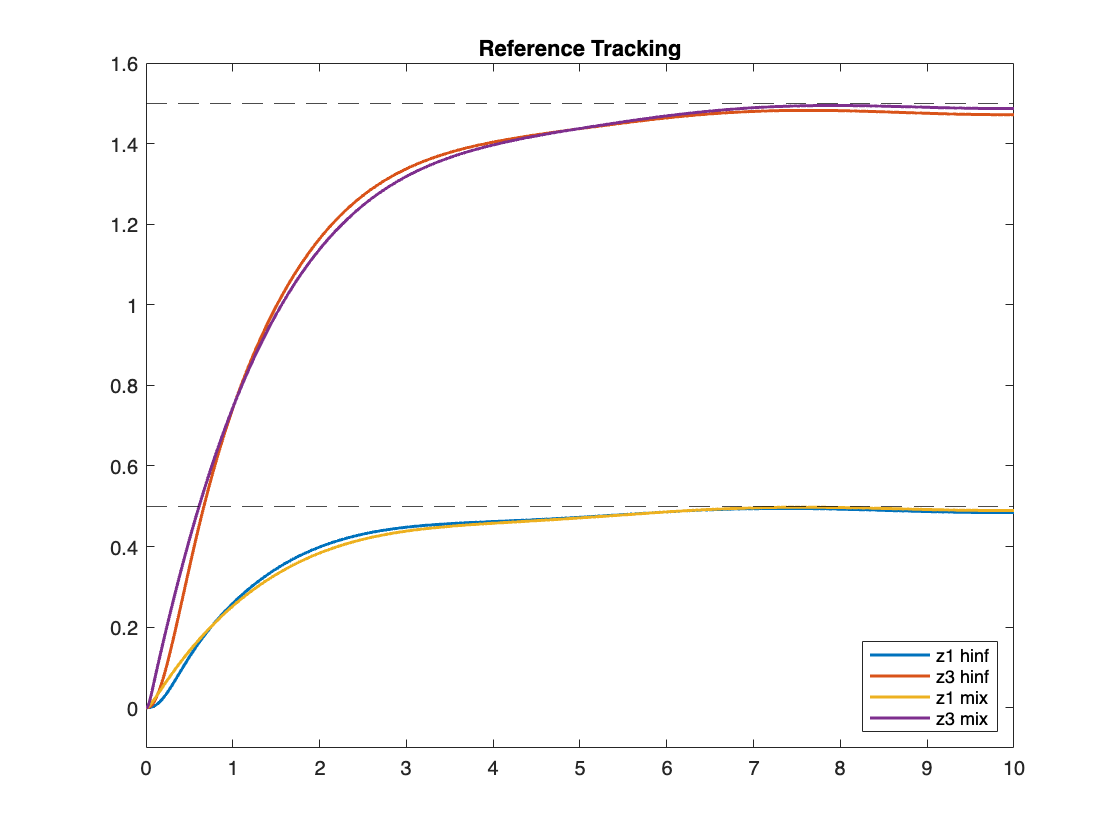

figure()
plot(t1, -(y1(:,1)-r(1)),t1, -(y1(:,2)-r(2)),t2, -(y2(:,1)-r(1)),t2, -(y2(:,2)-r(2)),'LineWidth',1.5)
yline(r(1),'k--');
yline(r(2),'k--');
ylim([-0.1,1.6])
title("Reference Tracking")
legend("z1 hinf",'z3 hinf',"z1 mix",'z3 mix','Location','southeast')

#### Control Effort Plot

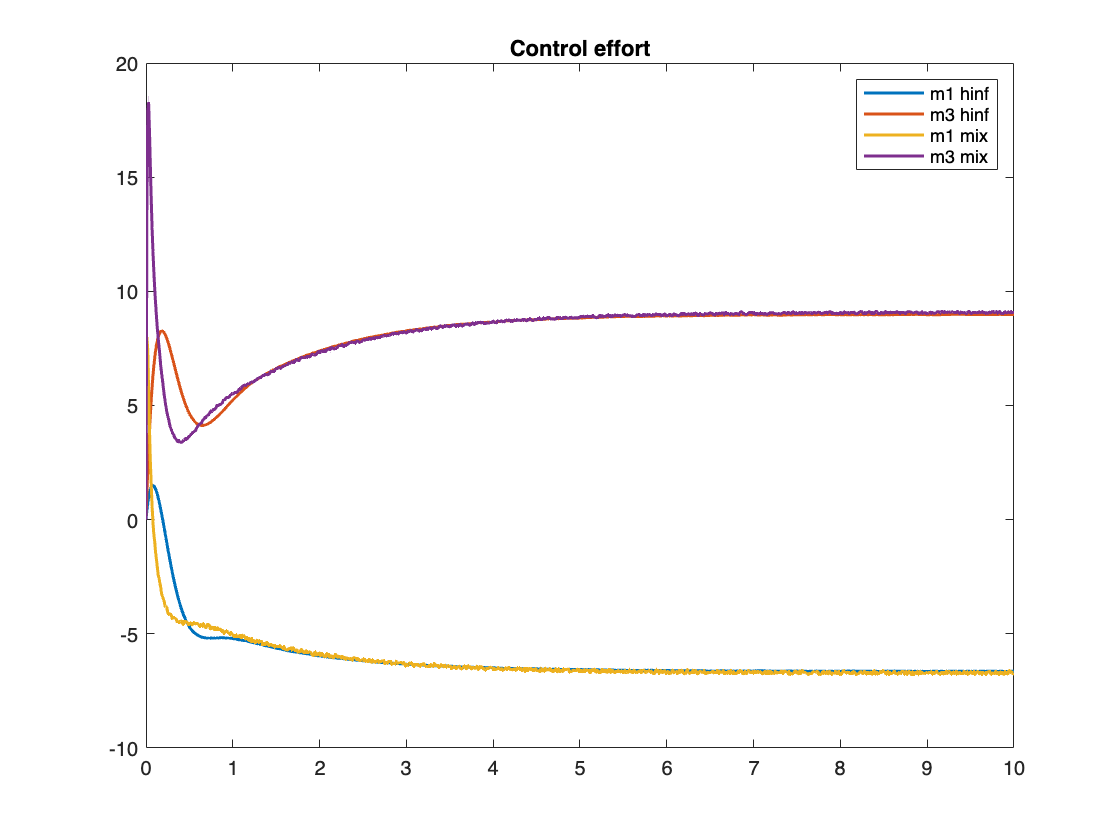

figure()
plot(t1, y1(:,3),t1, y1(:,4),t2, y2(:,3),t2, y2(:,4),'LineWidth',1.5)

title("Control effort")
legend("m1 hinf",'m3 hinf',"m1 mix",'m3 mix')

# Robust Stability

Let's see how does our controller perform on the uncertain plant.

We add uncertainty on the three masses. 

m1_unc = ureal('m1',m1,'Percentage',10,'AutoSimplify','full');
m2_unc = ureal('m2',m2,'Percentage',10,'AutoSimplify','full');
m3_unc = ureal('m3',m3,'Percentage',10,'AutoSimplify','full');

k0 =5;
k1 =10;
k2 =100;

mu1 = 5;
mu2 = 15;

d1 = 0.1; 
d2 = 0.2; 
d3 = 0.1;

A11 = zeros(3,3);
A12 = eye(3);
A21_unc = [-(k0+k1)/m1_unc k1/m1_unc 0;
        k1/m2_unc -(k1+k2)/m2_unc k2/m2_unc;
        0 k2/m3_unc -k2/m3_unc];
A22_unc = [-(mu1+d1)/m1_unc mu1/m1_unc 0;
        mu1/m2_unc -(mu1+mu2+d2)/m2_unc mu2/m2_unc
        0 mu2/m3_unc -(mu2+d3)/m3_unc];
A_unc = [A11, A12;
    A21_unc, A22_unc];
B_unc = [zeros(3,2); 1/m1_unc 0; 0 0; 0 1/m3_unc];

C = [[1 0 0; 0 0 1], zeros(2,3)];

D = zeros(2,2);

MSD_unc = ss(A_unc,B_unc,C,D);

MSD_unc.StateName = {'m1 displacement (m)';'m2 displacement (m)';'m3 displacement (m)';...
                  'm1 velocity (m/s)';'m2 velocity (m/s)';'m3 velocity (m/s)'};
MSD_unc.y  = {'z1','z3'};
MSD_unc.u = {'f1';'f3';};

## Full Complex Additive Representation

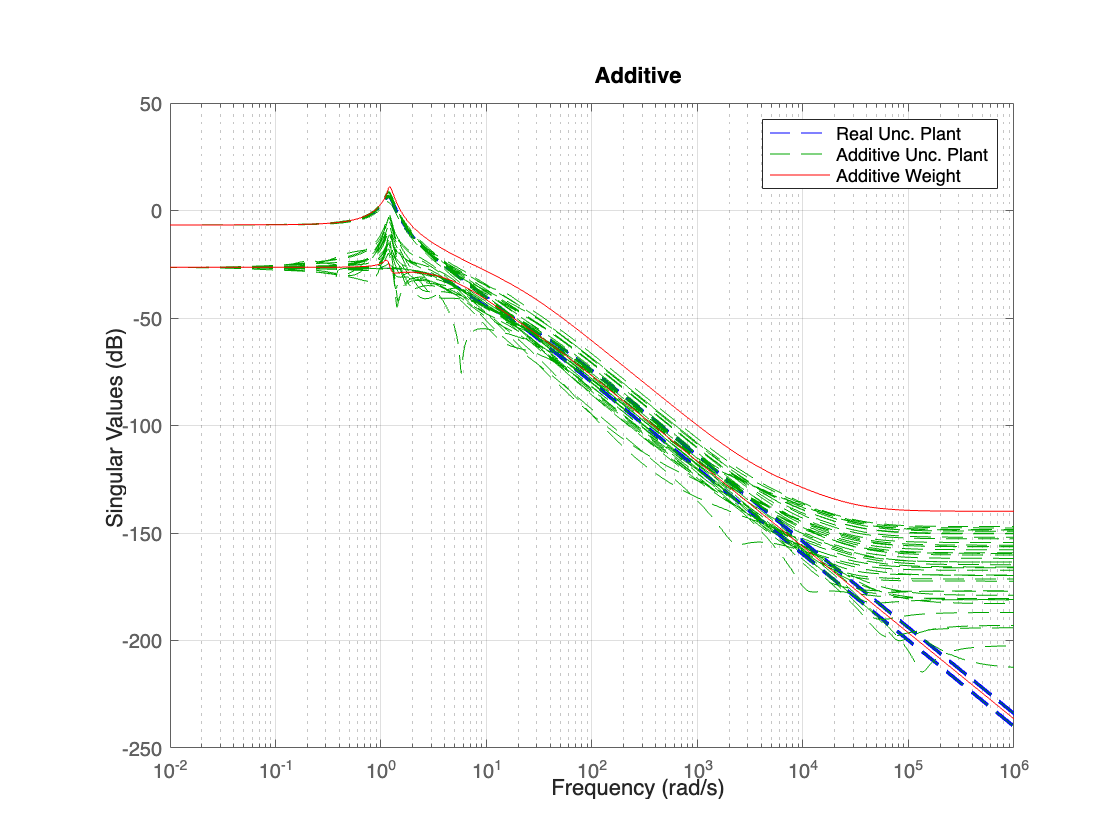

Gnom = (MSD_unc.NominalValue);
Gsamp = (gridureal(MSD_unc,20));

% Additive Representation
[~,infoAdd] = ucover(Gsamp,Gnom,3,'Additive');
wAdd = infoAdd.W1;
Delta = ultidyn('Delta',[2,2]);

% F.C. Additive uncertain Plant
Gunc_Add = Gnom + wAdd*Delta;
figure()
sigma(MSD_unc,'b--',Gunc_Add,'g--', Gnom+wAdd,'r'), grid
title('Additive')
legend('Real Unc. Plant','Additive Unc. Plant', 'Additive Weight','Location','northeast')

CLoop_add = feedback(Gunc_Add*C1,eye(2));
[stabmarg_add,wc] = robstab(CLoop_add)

stabmarg_add = struct with fields:
           LowerBound: 0.0607
           UpperBound: 0.0609
    CriticalFrequency: 1.1911


wc = struct with fields:
    Delta: [2×2 ss]


%hinfnorm(Wc_mul*loopsens(Gnom,Cc).To) 
hinfnorm(wAdd*C1*loopsens(Gnom,C1).So)

ans = 16.4278

L_unc = MSD_unc*C1;
L_nom = tf(minreal(L_unc.Nominal));

2 states removed.


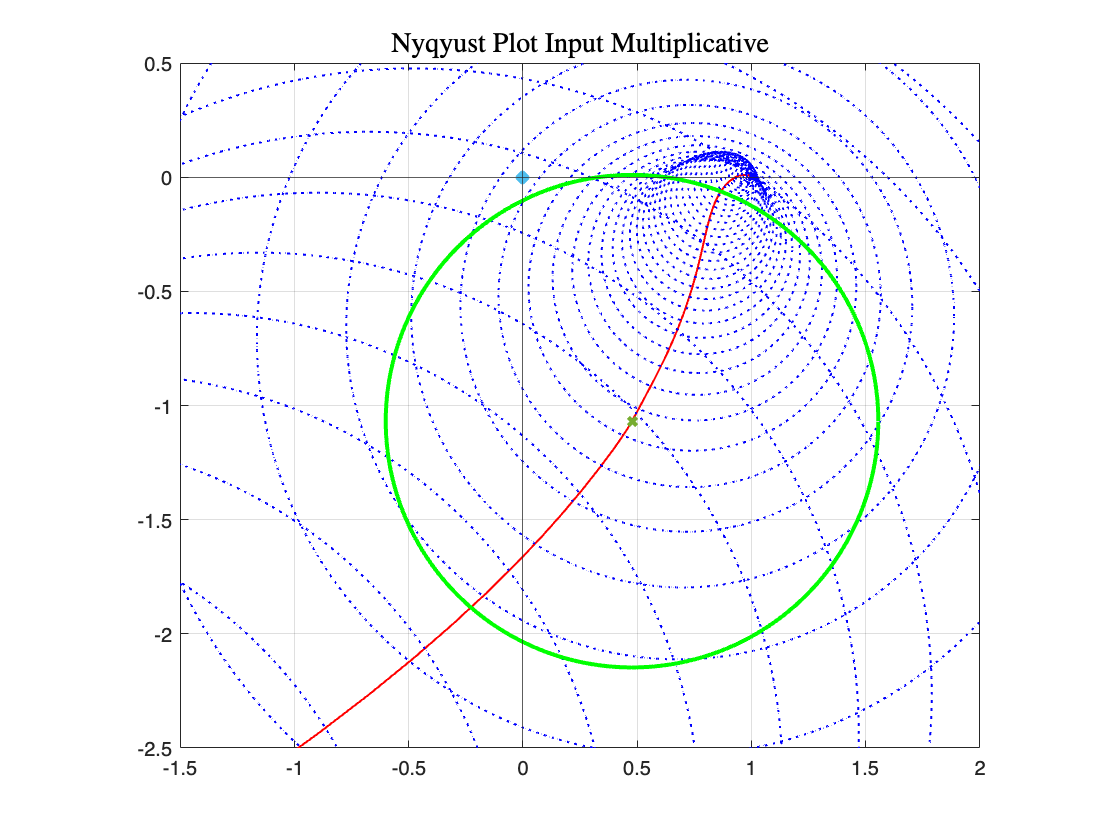


om = logspace(-1,2,100);
n = length(om);
alpha = 0:0.01:2*pi;
LL = eye(2)+L_nom;
Lprov = tf(minreal(LL(1,1)*LL(2,2) - LL(1,2)*LL(2,1)));
[ReL,ImL]=nyquist(Lprov, om);

crit_w = stabmarg_add.CriticalFrequency;
upper_b = stabmarg_add.UpperBound;
figure()
grid
plot(ReL(:),ImL(:),'-r','LineWidth',1), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Lprov,om(i));

    [radius,~]=sigma( C1*wAdd, om(i));
    plot(ReLw + max(radius)*cos(alpha),ImLw + max(radius)*sin(alpha),':b','LineWidth',1);
end
[ReLw,ImLw]=nyquist(Lprov,crit_w);
[radius,~]=sigma(C1*wAdd, crit_w);
plot(ReLw + upper_b*max(radius)*cos(alpha),ImLw + upper_b*max(radius)*sin(alpha),'g',ReLw,ImLw,"x", 'LineWidth',2)
plot(0,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Nyqyust Plot Input Multiplicative','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',14);
xline(0);
yline(0);
xlim([-1.5 2])
ylim([-2.5 0.5])
hold off

## Full Complex Input Multiplicative Representation

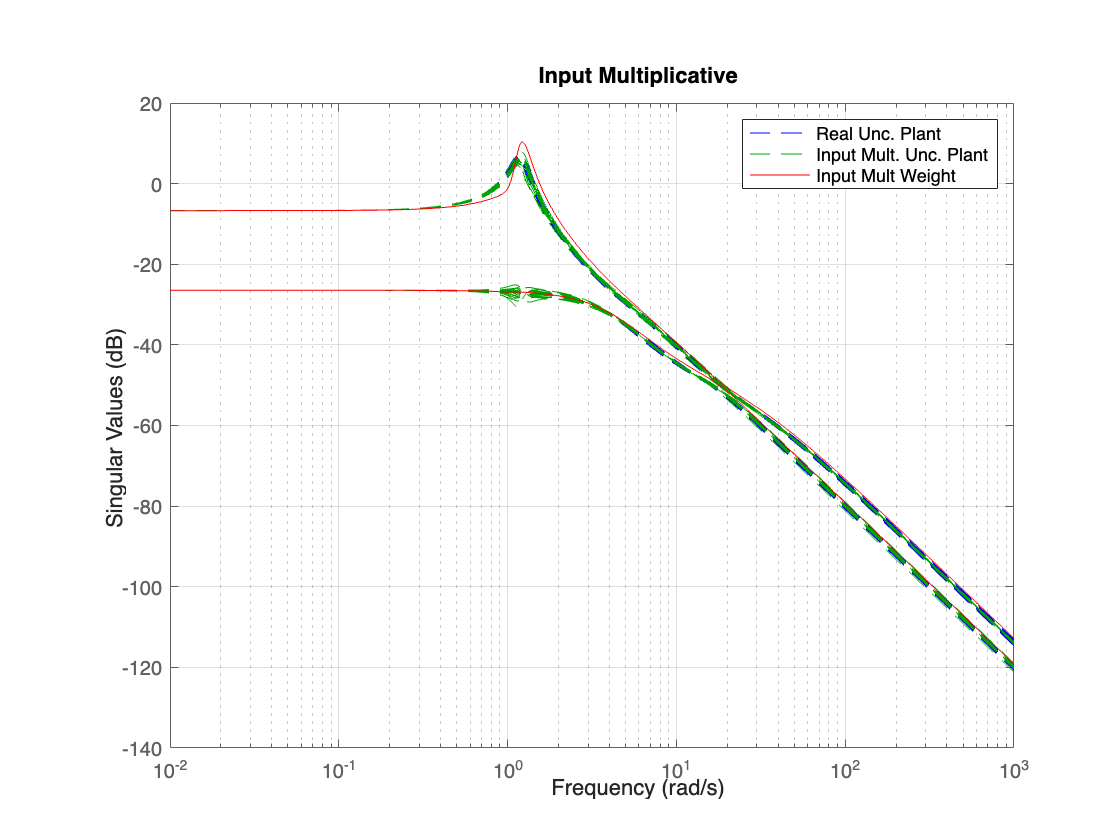

% Input Multiplicative Representation
[~,infoInMult] = ucover(Gsamp,Gnom,3,'InputMult');
wInMult = infoInMult.W1;

% F.C. Input Multiplicative uncertain Plant
Gunc_InMult = Gnom*(eye(2) + wInMult*Delta);

figure()
sigma(MSD_unc,'b--',Gunc_InMult,'g--', Gnom*(eye(2) + wInMult),'r'), grid
title('Input Multiplicative')
legend('Real Unc. Plant','Input Mult. Unc. Plant', 'Input Mult Weight','Location','northeast')

CLoop_InMult = feedback(Gunc_InMult*C2,eye(2));
[stabmarg_InMult,wc] = robstab(CLoop_InMult)

stabmarg_InMult = struct with fields:
           LowerBound: 3.1824
           UpperBound: 3.1888
    CriticalFrequency: 1.2023


wc = struct with fields:
    Delta: [2×2 ss]


hinfnorm(wInMult * loopsens(Gnom,C1).Ti )

ans = 0.3554

L_unc = MSD_unc*C1;
L_nom = tf(minreal(L_unc.Nominal));

2 states removed.


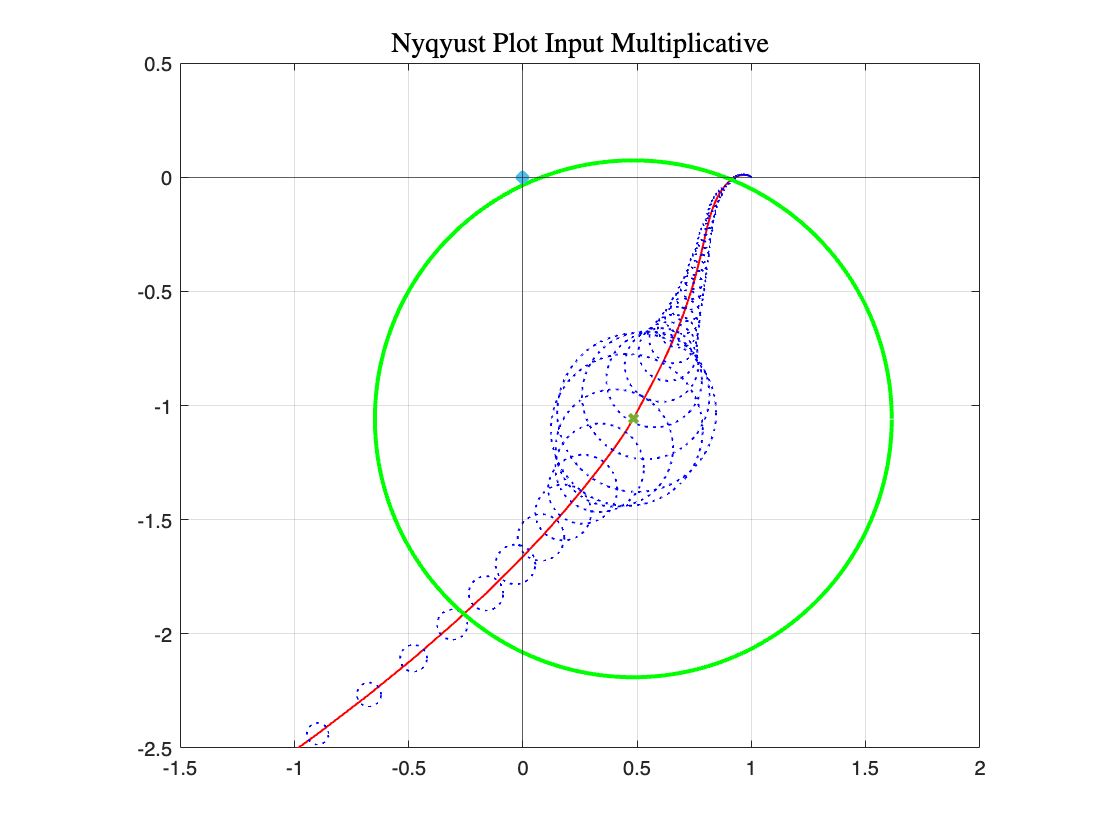


om = logspace(-1,2,100);
n = length(om);
alpha = 0:0.01:2*pi;
LL = eye(2)+L_nom;
Lprov = tf(minreal(LL(1,1)*LL(2,2) - LL(1,2)*LL(2,1)));
[ReL,ImL]=nyquist(Lprov, om);

crit_w = stabmarg_InMult.CriticalFrequency;
upper_b = stabmarg_InMult.UpperBound;
figure()
grid
plot(ReL(:),ImL(:),'-r','LineWidth',1), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Lprov,om(i));

    [radius,~]=sigma( wInMult * L_nom, om(i));
    plot(ReLw + max(radius)*cos(alpha),ImLw + max(radius)*sin(alpha),':b','LineWidth',1);
end
[ReLw,ImLw]=nyquist(Lprov,crit_w);
[radius,radiusp]=sigma(wInMult * L_nom, crit_w);
plot(ReLw + upper_b*max(radius)*cos(alpha),ImLw + upper_b*max(radius)*sin(alpha),'g',ReLw,ImLw,"x", 'LineWidth',2)
plot(0,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Nyqyust Plot Input Multiplicative','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',14);
xline(0);
yline(0);
xlim([-1.5 2])
ylim([-2.5 0.5])
hold off

## Full Complex Output Multiplicative Representation

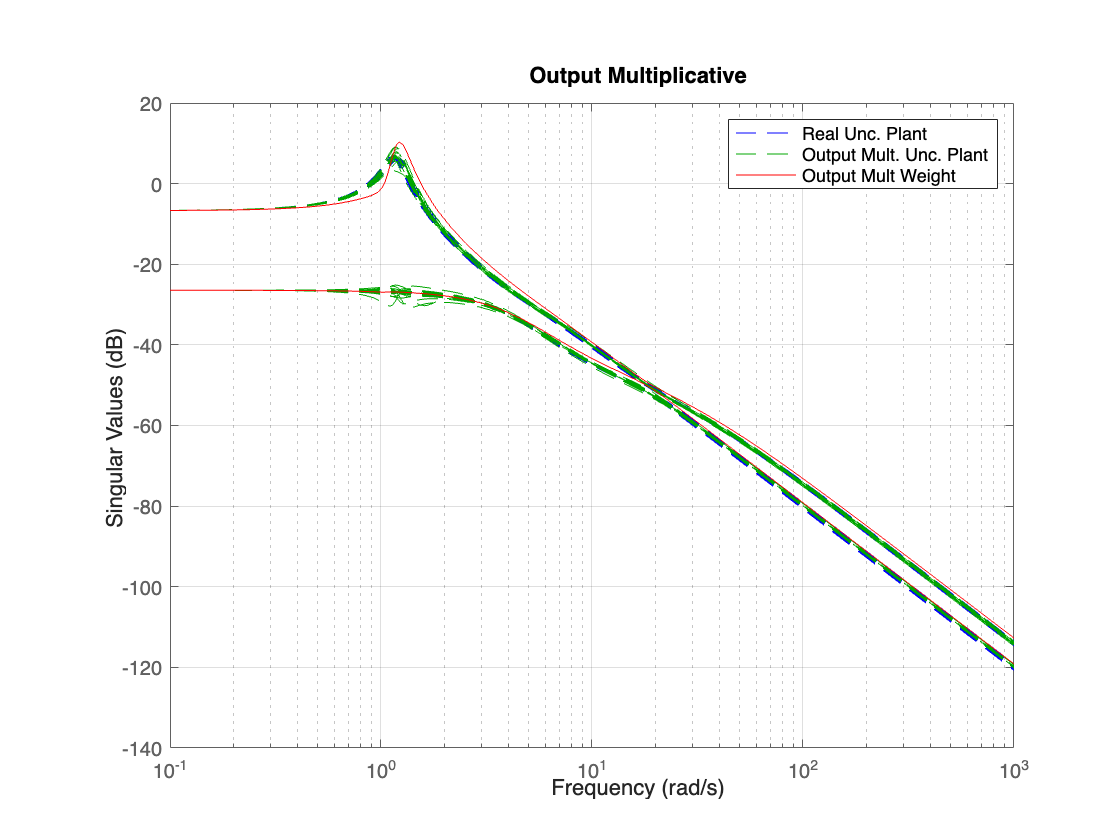

% Output Multiplicative Representation
[~,infoOutMult] = ucover(Gsamp,Gnom,3,'OutputMult');
wOutMult = infoOutMult.W1;

% F.C. Output Multiplicative uncertain Plant
Gunc_OutMult = Gnom*(eye(2) + wOutMult*Delta);

figure()
sigma(MSD_unc,'b--',Gunc_OutMult,'g--', (eye(2) + wOutMult)*Gnom,'r'), grid
title('Output Multiplicative')
legend('Real Unc. Plant','Output Mult. Unc. Plant', 'Output Mult Weight','Location','northeast')

CLoop_OutMult = feedback(Gunc_OutMult*C2,eye(2));
[stabmarg_OutMult,wc] = robstab(CLoop_OutMult)

stabmarg_OutMult = struct with fields:
           LowerBound: 3.1914
           UpperBound: 3.1978
    CriticalFrequency: 1.2023


wc = struct with fields:
    Delta: [2×2 ss]


hinfnorm(wOutMult*loopsens(Gnom,C1).To) 

ans = 0.3273

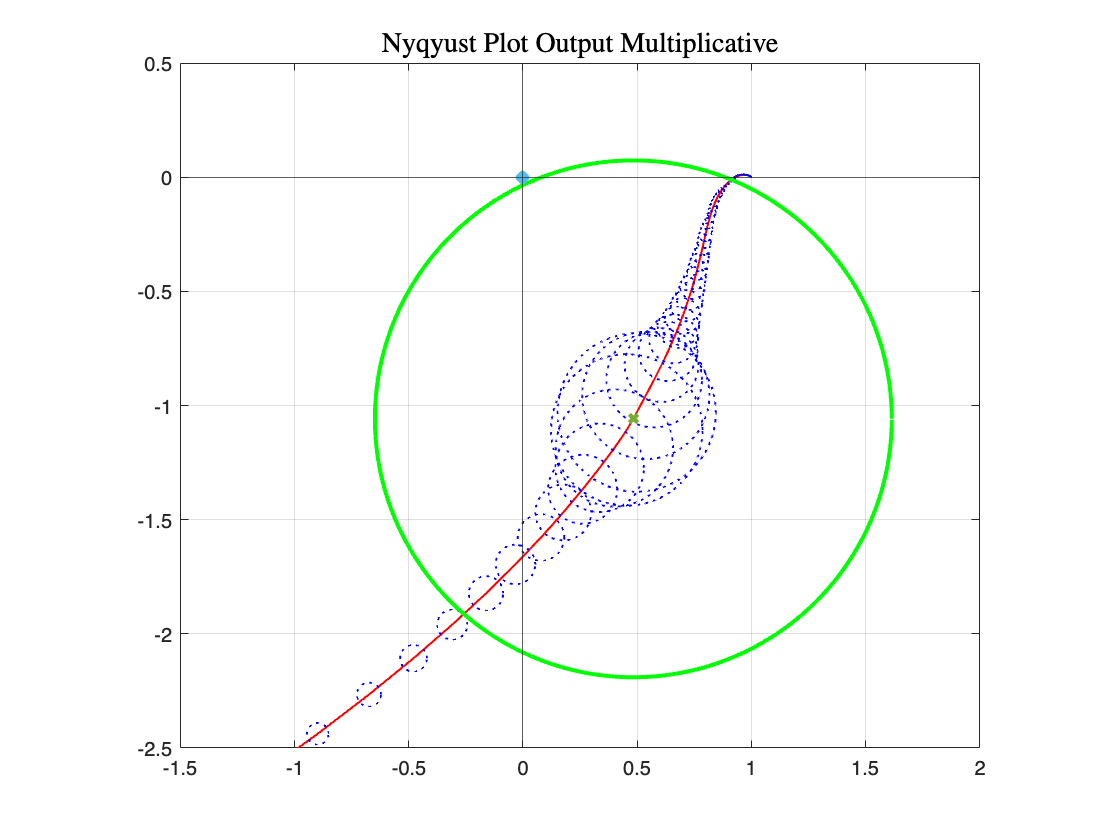

om = logspace(-1,2,100);
n = length(om);
alpha = 0:0.01:2*pi;
LL = eye(2)+L_nom;
Lprov = tf(minreal(LL(1,1)*LL(2,2) - LL(1,2)*LL(2,1)));
[ReL,ImL]=nyquist(Lprov, om);

crit_w = stabmarg_OutMult.CriticalFrequency;
upper_b = stabmarg_OutMult.UpperBound;
figure()
grid
plot(ReL(:),ImL(:),'-r','LineWidth',1), hold on
for i=1:n
   [ReLw,ImLw]=nyquist(Lprov,om(i));

    [radius,~]=sigma( L_nom*wOutMult, om(i));
    plot(ReLw + max(radius)*cos(alpha),ImLw + max(radius)*sin(alpha),':b','LineWidth',1);
end
[ReLw,ImLw]=nyquist(Lprov,crit_w);
[radius,radiusp]=sigma(L_nom * wOutMult, crit_w);
plot(ReLw + upper_b*max(radius)*cos(alpha),ImLw + upper_b*max(radius)*sin(alpha),'g',ReLw,ImLw,"x", 'LineWidth',2)
plot(0,0,"x","MarkerSize",6,'LineWidth',4)
axis equal
grid
Tit=title('Nyqyust Plot Output Multiplicative','Interpreter','latex');
set(Tit,'FontName','Courier','FontSize',14);
xline(0);
yline(0);
xlim([-1.5 2])
ylim([-2.5 0.5])
hold off

# Structured Real Uncertainty SSV

CLoop_str = loopsens(MSD_unc,C1).To;
[stabmarg,wc] = robstab(CLoop_str)

stabmarg = struct with fields:
           LowerBound: 4.7627
           UpperBound: 4.7724
    CriticalFrequency: 1.0218


wc = struct with fields:
    m1: 1.4772
    m2: 2.2159
    m3: 0.7386


## Build Augmented Plant

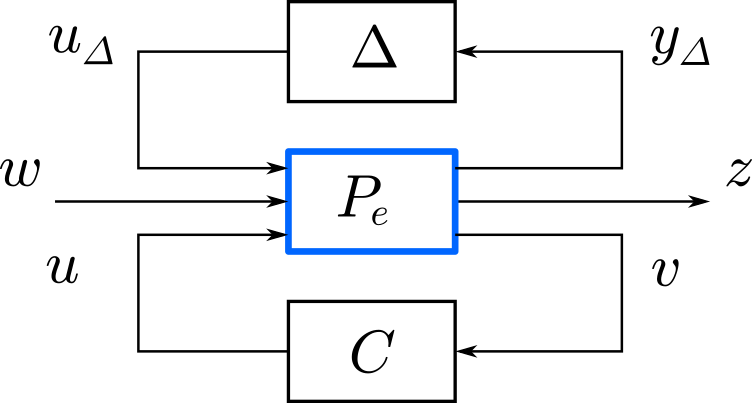 

om = logspace(-2,2,200);

MSD_unc.u = 'u_bar'; MSD_unc.y = 'y';

% "Pull out" the uncertainty from Plant
[P_cert,delta,BlkStruct] = lftdata(MSD_unc);
n_u = length(delta);
P_cert.InputGroup.uncert_u = [1:n_u];
P_cert(:,'uncert').u = 'unc_u';
P_cert.OutputGroup.uncert_y = [1:n_u];
P_cert('uncert',:).y = 'unc_y';

% Build augmented Plant
Pe_cert = minreal(connect(P_cert, Gd, Sum1,Sum2,Sum3, {'unc_u','r','d','n','u'},{'unc_y','ey','u','v'}));

18 states removed.


% Close Controller loop (lower LFT)
Cl_cert = lft(Pe_cert,C1);

% Extract N11 block (M)
M = Cl_cert(1:n_u,1:n_u);

% structured uncertainty: 3 real uncertain parameters
blockdiag = [-1 0; -1 0; -1 0]; 

% Calculate SSV bounds
ssv_bounds1 = mussv(frd(M,om),blockdiag);

Points completed: 200/200


[ssv_1,~] = bode(ssv_bounds1(1,1),om);

### Try to quadruple the uncertainty

m1_unc = ureal('m1',m1,'Percentage',40,'AutoSimplify','full');
m2_unc = ureal('m2',m2,'Percentage',40,'AutoSimplify','full');
m3_unc = ureal('m3',m3,'Percentage',40,'AutoSimplify','full');

A21_unc = [-(k0+k1)/m1_unc k1/m1_unc 0;
        k1/m2_unc -(k1+k2)/m2_unc k2/m2_unc;
        0 k2/m3_unc -k2/m3_unc];
A22_unc = [-(mu1+d1)/m1_unc mu1/m1_unc 0;
        mu1/m2_unc -(mu1+mu2+d2)/m2_unc mu2/m2_unc
        0 mu2/m3_unc -(mu2+d3)/m3_unc];
A_unc = [A11, A12;
    A21_unc, A22_unc];
B_unc = [zeros(3,2); 1/m1_unc 0; 0 0; 0 1/m3_unc];

MSD_4x = ss(A_unc,B_unc,C,D);

MSD_4x.u = 'u_bar'; MSD_4x.y = 'y';

% "Pull out" the uncertainty from Plant
[P_4x,~,~] = lftdata(MSD_4x);

P_4x.InputGroup.uncert_u = [1:n_u];
P_4x(:,'uncert').u = 'unc_u';
P_4x.OutputGroup.uncert_y = [1:n_u];
P_4x('uncert',:).y = 'unc_y';

% Build augmented Plant
Pe_4x = minreal(connect(P_4x, Gd, Sum1,Sum2,Sum3, {'unc_u','r','d','n','u'},{'unc_y','ey','u','v'}));

18 states removed.


% Close Controller loop (lower LFT)
Cl_4x = lft(Pe_4x,C1);

% Extract N11 block (M)
M = Cl_4x(1:n_u,1:n_u);

% Calculate SSV bounds
ssv_bounds2 = mussv(frd(M,om),blockdiag);

Points completed: 200/200


[ssv_2,~] = bode(ssv_bounds2(1,1),om);

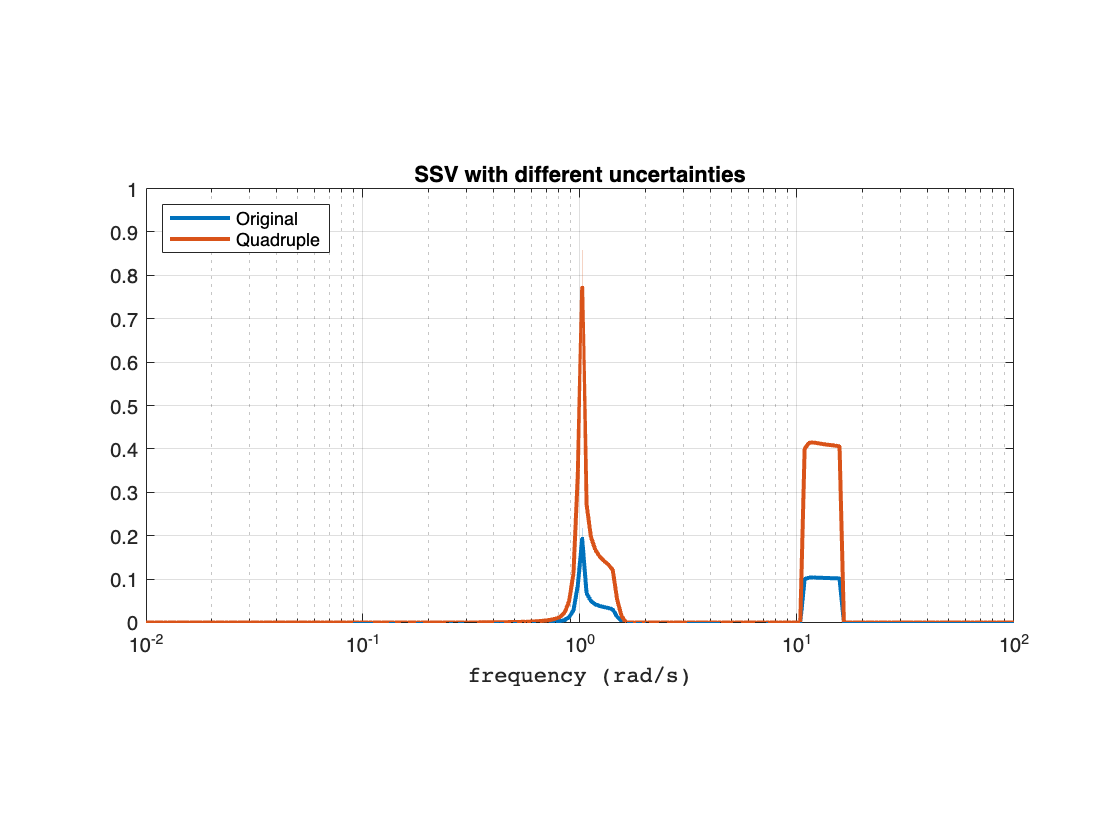

figure()
pl = semilogx(om,ssv_1(:),om,ssv_2(:), 'Linewidth',2); grid
yline(1)
xlabel('frequency (rad/s)','FontName','Courier');
legend('Original','Quadruple','Location','NorthWest')
title('SSV with different uncertainties')
pbaspect([2 1 1])

## Mu-Synthesis

Pe_mu = minreal(connect(MSD_unc, Gd, Sum1,Sum2,Sum3, wS_hinf, wU,Dn, {'r','d','n_bar','u'},{'ey_sens','u_sens','v'}));

[C_mu,rpMU1] = musyn(Pe_mu,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           9.992        9.976        9.992             2
    2           9.992        9.977        9.992             2
    3           9.992        9.977        9.992             2

Best achieved robust performance: 9.98



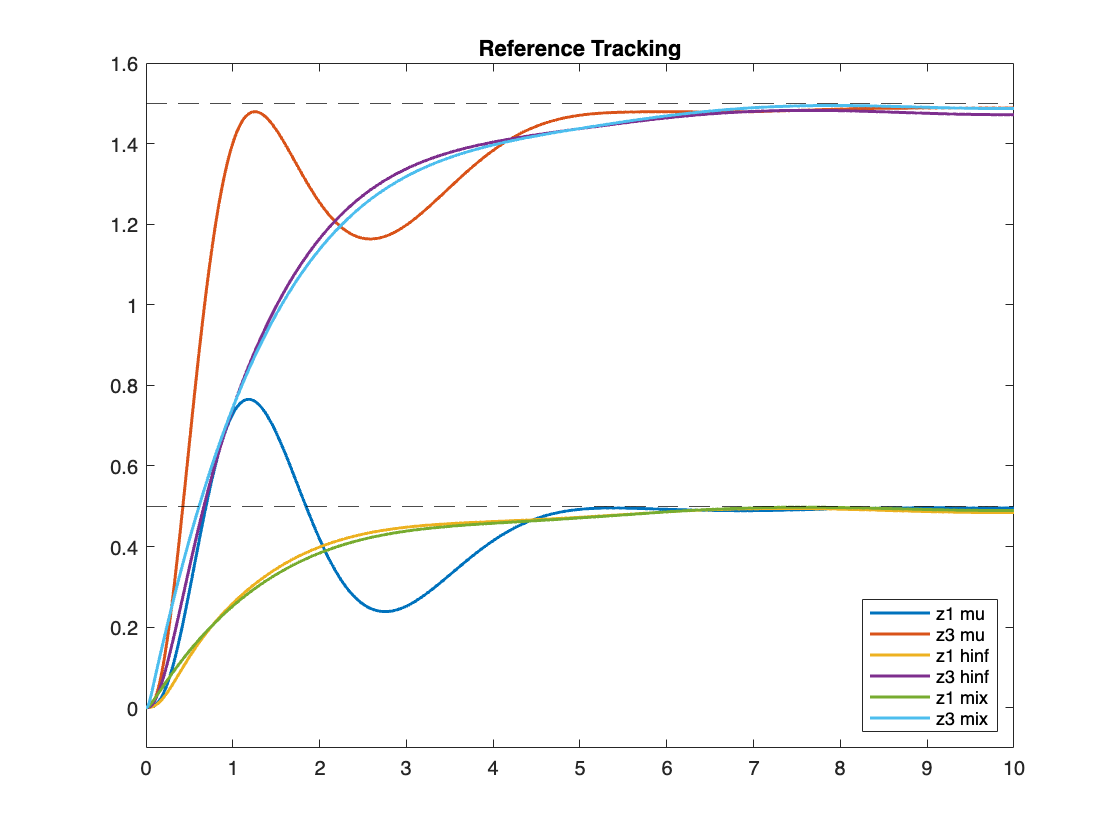

CLoop_mu = lft(Pe, C_mu);
[y_mu, t_mu] = lsim(CLoop_mu, input, t);


figure()
plot(t_mu, -(y_mu(:,1)-r(1)),t_mu, -(y_mu(:,2)-r(2)),t1, -(y1(:,1)-r(1)),t1, -(y1(:,2)-r(2)),t2, -(y2(:,1)...
    -r(1)),t2, -(y2(:,2)-r(2)),'LineWidth',1.5)
yline(r(1),'k--');
yline(r(2),'k--');
ylim([-0.1,1.6])
title("Reference Tracking")
legend("z1 mu",'z3 mu',"z1 hinf",'z3 hinf',"z1 mix",'z3 mix','Location','southeast')

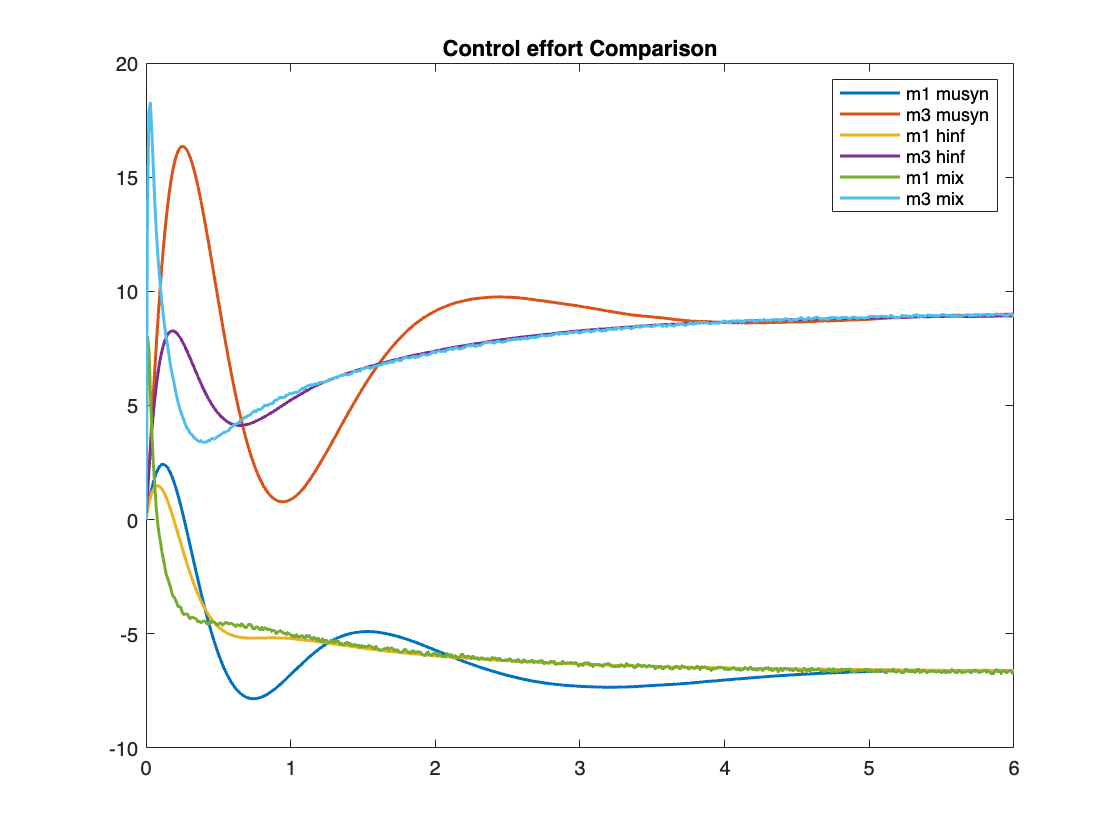

figure()
plot(t_mu, y_mu(:,3),t_mu, y_mu(:,4),t1, y1(:,3),t1, y1(:,4),t2, y2(:,3),t2, y2(:,4),'LineWidth',1.5)
xlim([0,6])
title("Control effort Comparison")
legend("m1 musyn",'m3 musyn',"m1 hinf",'m3 hinf',"m1 mix",'m3 mix')

#### Stability Robustness

CLoop_str_mu = loopsens(MSD_unc,C_mu).To;
[stabmarg,wc] = robstab(CLoop_str_mu)

stabmarg = struct with fields:
           LowerBound: 7.3524
           UpperBound: 7.3610
    CriticalFrequency: 5.8522


wc = struct with fields:
    m1: 0.2639
    m2: 0.3958
    m3: 0.1319


% Close Controller loop (lower LFT)
Cl_4x_mu = lft(Pe_4x,C_mu);

% Extract N11 block (M)
M = Cl_4x_mu(1:n_u,1:n_u);

% Calculate SSV bounds
ssv_bounds3 = mussv(frd(M,om),blockdiag);

Points completed: 200/200


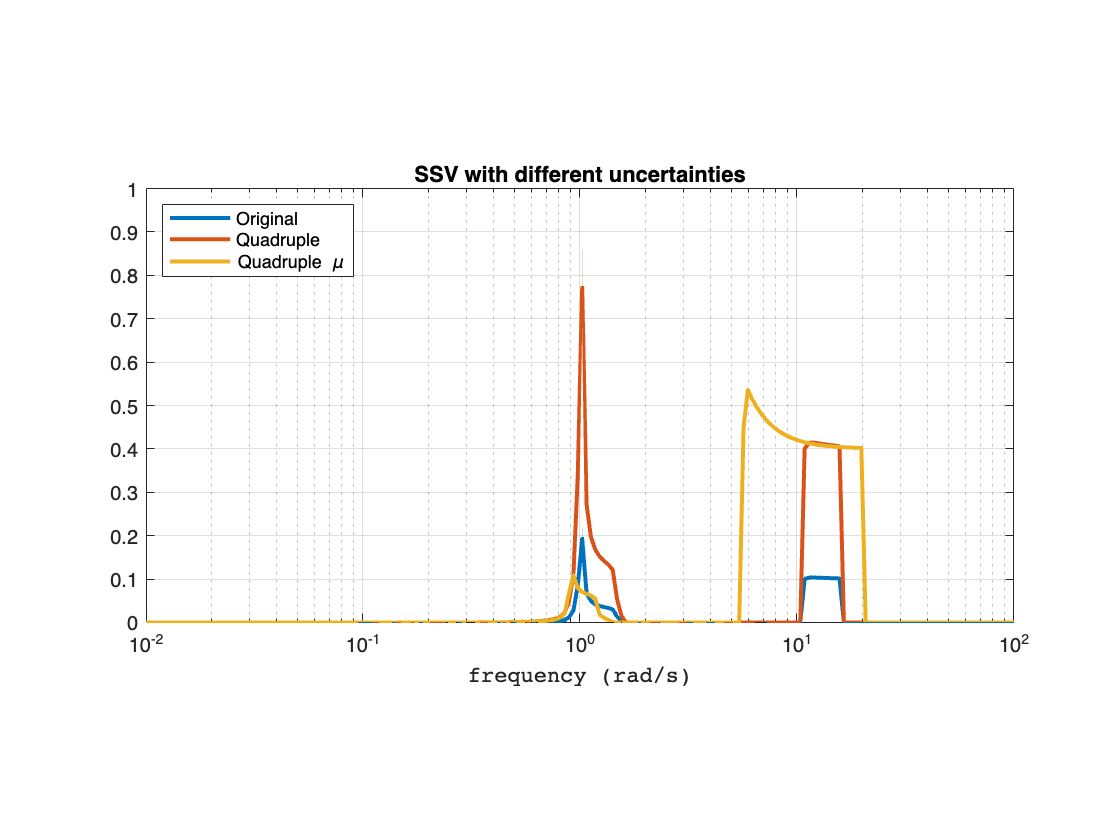

[ssv_3,~] = bode(ssv_bounds3(1,1),om);

figure()
pl = semilogx(om,ssv_1(:),om,ssv_2(:),om,ssv_3(:), 'Linewidth',2); grid
yline(1)
xlabel('frequency (rad/s)','FontName','Courier');
legend('Original','Quadruple','Quadruple \mu','Location','NorthWest')
title('SSV with different uncertainties')
pbaspect([2 1 1])